# Double Integrator Reach-Avoid Via Dynamic Programming

This example demonstrates how to use the SReachTools toolbox to solve a terminal-hitting time reach-avoid problem using [dynamic programming](https://doi.org/10.1016/j.automatica.2010.08.006).

In this example, we analyze the following problems via dynamic programming for a stochastic system with known dynamics:

- **stochastic viability problem: **Compute a controller to stay within a safe set with maximum likelihood

- **the terminal-hitting time stochastic reach-avoid problem: **Compute a controller that maximizes the probability of reaching a target set at a time horizon, `N`, while maintaining the system in a set of safe states

- **stochastic reachability of a moving target tube: **Compute a controller that maximizes the probability of staying within a target tube

SReachTools has a dynamic programing implementation that can analyze systems upto three dimensions. For efficient implementation, we require the input set to be an axis-aligned hypercuboid, and define the grid the smallest hypercuboid containing all the target sets.

## Notes about this Live Script:

- **MATLAB dependencies**: This Live Script uses MATLAB's  [Statistics and Machine Learning Toolbox](https://www.mathworks.com/products/statistics.html). 

- **External dependencies**: This Live Script uses Multi-Parameteric Toolbox ([MPT](http://people.ee.ethz.ch/~mpt/3/)). 

- Make sure that `srtinit` is run before running this script.

This Live Script is part of the SReachTools toolbox. License for the use of this function is given in [https://github.com/unm-hscl/SReachTools/blob/master/LICENSE](https://github.com/unm-hscl/SReachTools/blob/master/LICENSE).

# Problem setup

## Double Integrator

In this example we use a discretized double integrator dynamics given by:


$$  x_{k+1} = \left[ \begin{array}{cc}
    1 & T \\
    0 & 1
  \end{array}\right] x_{k} + \left[\begin{array}{c}
    \frac{T^{2}}{2} \\
    T
  \end{array}\right] u_{k} + w_{k}$$


where $T$ is the discretization time-step, and $w_{k}$ is the stochastic disturbance.

## Setup the system

% discretization parameter
T = 0.1;

% define the system
sys = LtiSystem('StateMatrix', [1, T; 0, 1], ...
    'InputMatrix', [T^2/2; T], ...
    'InputSpace', Polyhedron('lb', -0.1, 'ub', 0.1), ...
    'DisturbanceMatrix', eye(2), ...
    'Disturbance', StochasticDisturbance('Gaussian', zeros(2,1), 0.01*eye(2)));

## Setup the dynamic programming and visualization parameters

dyn_prog_xinc = 0.05;
dyn_prog_uinc = 0.1;
reach_set_thresholds = [0.2 0.5 0.9];
legend_str={'Target tube at t=0', 'Safety Probability $\geq 0.2$', 'Safety Probability $\geq 0.5$', 'Safety Probability $\geq 0.9$'};

# Case 1: Terminal hitting-time stochatsic reach-avoid problem (Constant target sets uptil time horizon - 1 and potentially a different target set at time horizon)

## Setup the target and safe sets

safe_set = Polyhedron('lb', [-1, -1], 'ub', [1, 1]);
axis_vec1 = [-1 1 -1 1];

## Setup the target tube

Target tube is a generalization of the reach problem. The reach avoid target-tube is created by setting the first $N-1$ sets in the tube as the `safe_set` and the final set as the `target_set`.

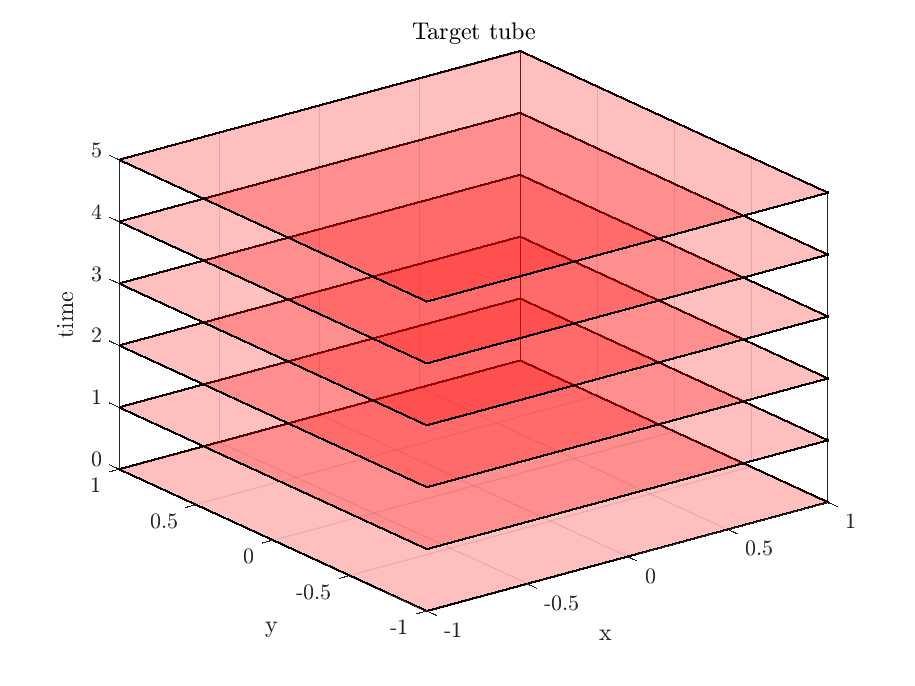

% time horizon
N = 5;
% in target tube for the viability problem is equivalent to a tube of repeating
% safe sets
target_tube1 = TargetTube('viability', safe_set, N);

% Plotting of target tube
figure()
hold on    
for time_indx=0:N
    target_tube_at_time_indx = Polyhedron('H',[target_tube1(time_indx+1).A,zeros(size(target_tube1(time_indx+1).A,1),1), target_tube1(time_indx+1).b], 'He',[0 0 1 time_indx]);
    plot(target_tube_at_time_indx, 'alpha',0.25);
end
axis([axis_vec1 0 N])
box on;
grid on;
xlabel('x');
ylabel('y');
zlabel('time');
title('Target tube');

## Dynamic programming recursion via gridding

tic;
[prob_x1, cell_of_xvec_x1] = getDynProgSolForTargetTube(sys, dyn_prog_xinc, dyn_prog_uinc, target_tube1);

Set optimal value function at t=5
Compute transition probability...100%
Compute optimal value function at t=4
Compute optimal value function at t=3
Compute optimal value function at t=2
Compute optimal value function at t=1
Compute optimal value function at t=0


toc

Elapsed time is 5.619776 seconds.


## Visualization of the value function at t=0 (safety probability)

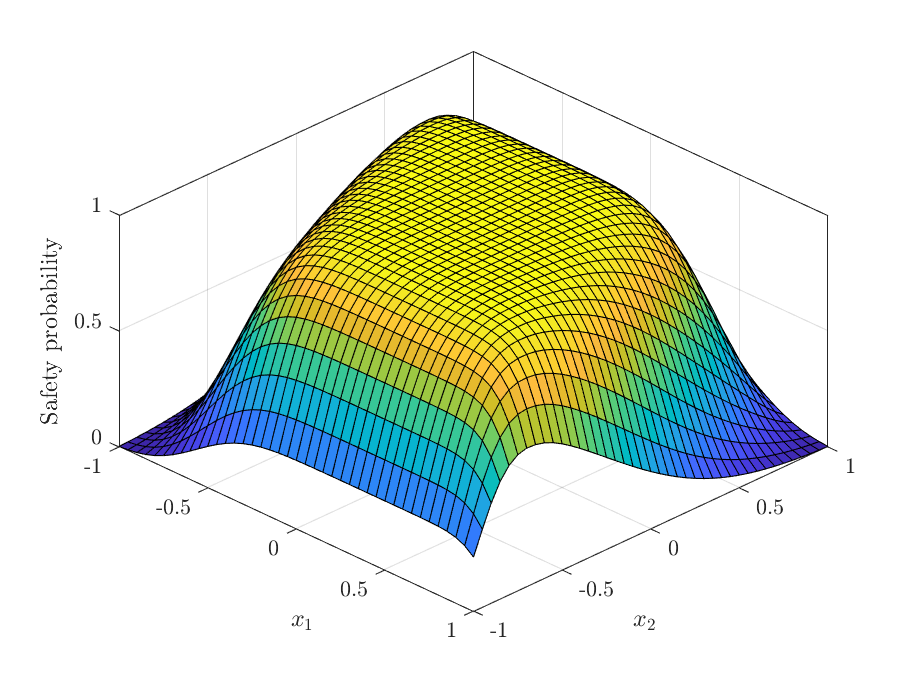

figure();
x1vec = cell_of_xvec_x1{1};
x2vec = cell_of_xvec_x1{2};
surf(x1vec,x2vec,reshape(prob_x1,length(x2vec),length(x1vec)));
axis([axis_vec1 0 1])
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
zlabel('Safety probability')
box on
view(45, 45)

## Visualization of the safe initial sets --- Superlevel sets of safety probability

figure();
poly_array1 = getDynProgLevelSets2D(cell_of_xvec_x1, prob_x1, reach_set_thresholds, target_tube1);

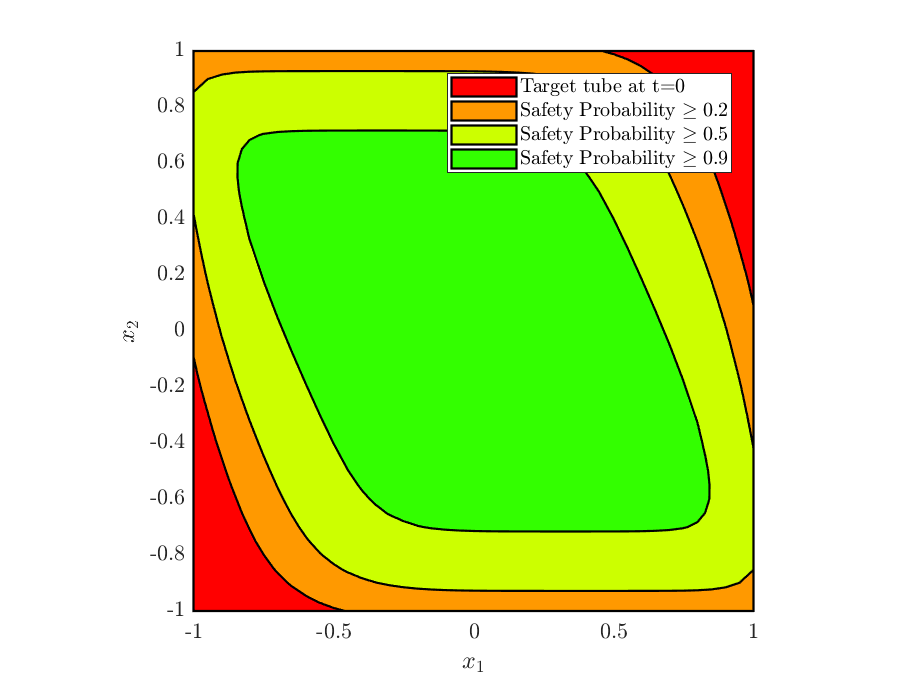

hold on;
plot([target_tube1(1), poly_array1])
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
box on
axis(axis_vec1)
axis equal
legend(legend_str)

# Case 2: Terminal hitting-time stochastic reach-avoid

## Setup the time-varying target tube

The advantage of target tube is that it allows for problem formulations in which we would like to reach a moving target.

## Setup the target and safe sets

safe_set = Polyhedron('lb', [-1, -1], 'ub', [1, 1]);
target_set = Polyhedron('lb', [-0.5, -0.5], 'ub', [0.5, 0.5]);
axis_vec2 = [-1 1 -1 1];

## Setup the target tube

Target tube is a generalization of the reach problem. The reach avoid target-tube is created by setting the first $N-1$ sets in the tube as the `safe_set` and the final set as the `target_set`.

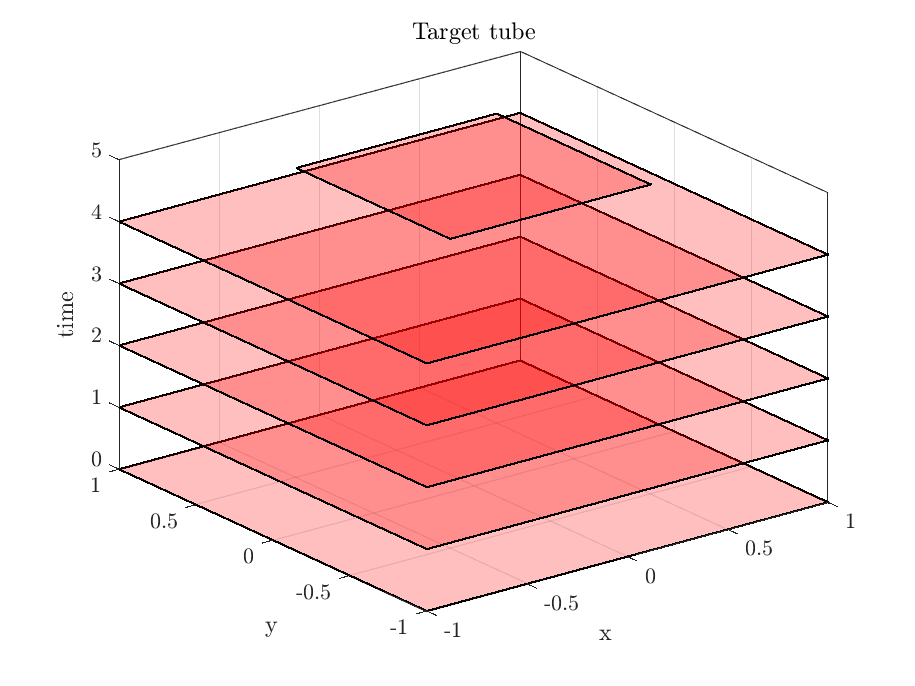

% time horizon
N = 5;
% in target tube for the viability problem is equivalent to a tube of repeating
% safe sets
target_tube2 = TargetTube('reach-avoid', safe_set, target_set, N);

% Plotting of target tube
figure()
hold on    
for time_indx=0:N
    target_tube_at_time_indx = Polyhedron('H',[target_tube2(time_indx+1).A,zeros(size(target_tube2(time_indx+1).A,1),1), target_tube2(time_indx+1).b], 'He',[0 0 1 time_indx]);
    plot(target_tube_at_time_indx, 'alpha',0.25);
end
axis([axis_vec2 0 N])
box on;
grid on;
xlabel('x');
ylabel('y');
zlabel('time');
title('Target tube');

## Dynamic programming solution on target tube

tic;
[prob_x2, cell_of_xvec_x2] = getDynProgSolForTargetTube(sys, dyn_prog_xinc, dyn_prog_uinc, target_tube2);

Set optimal value function at t=5
Compute transition probability...100%
Compute optimal value function at t=4
Compute optimal value function at t=3
Compute optimal value function at t=2
Compute optimal value function at t=1
Compute optimal value function at t=0


toc

Elapsed time is 5.635163 seconds.


## Visualization of the value function at t=0 (safety probability)

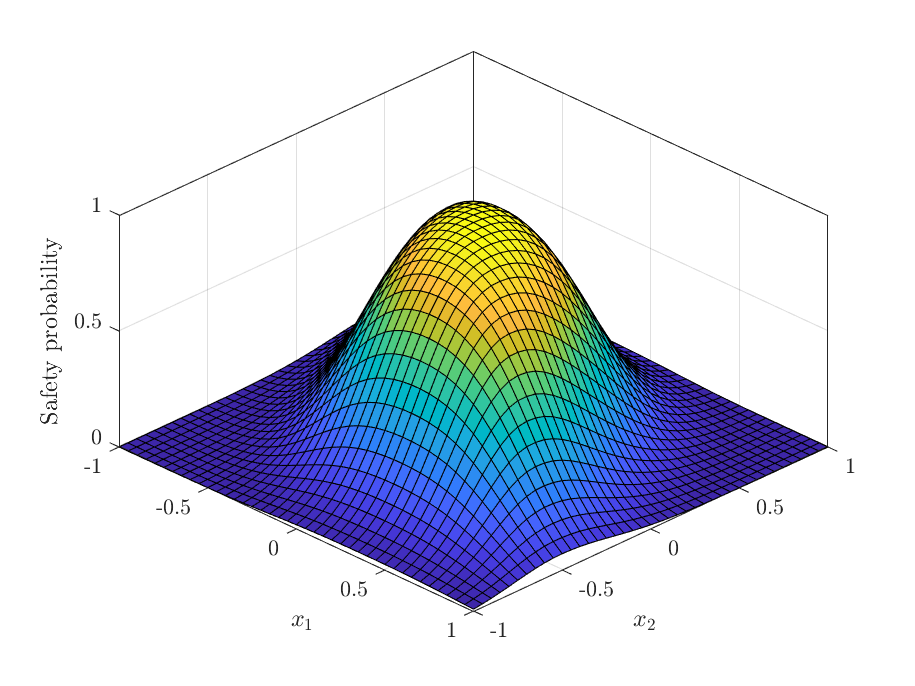

figure();
x1vec = cell_of_xvec_x2{1};
x2vec = cell_of_xvec_x2{2};
axis([axis_vec2 0 N]);
surf(x1vec,x2vec,reshape(prob_x2,length(x2vec),length(x1vec)));
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
zlabel('Safety probability')
box on
view(45, 45)

## Visualization of the safe initial sets --- Superlevel sets of safety probability

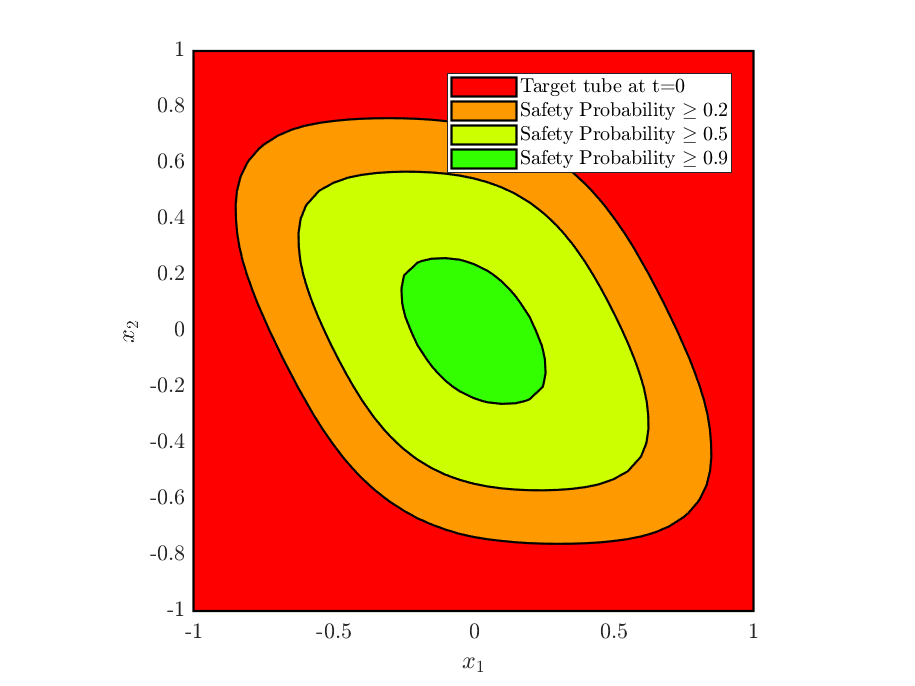

figure();
poly_array2 = getDynProgLevelSets2D(cell_of_xvec_x2, prob_x2, reach_set_thresholds, target_tube2);
hold on;
plot([target_tube2(1) poly_array2])
box on
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
axis(axis_vec2);
box on
axis equal
legend(legend_str)

# Case 3: Time-varying target sets

## Setup the time-varying target tube

The advantage of target tube is that it allows for problem formulations in which we would like to reach a moving target.

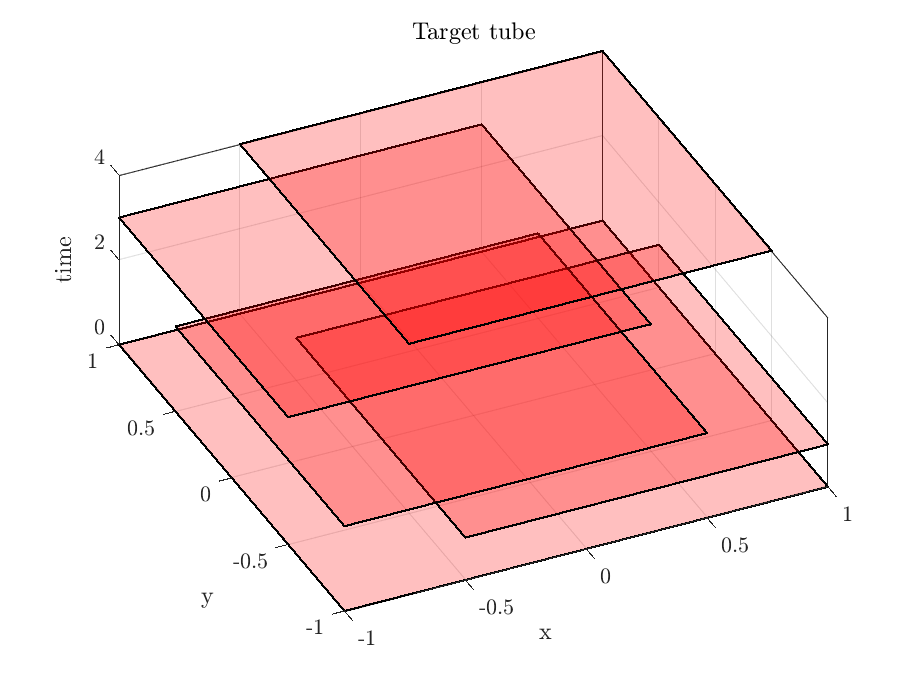

target_tube3 = TargetTube(Polyhedron('lb', [-1, -1], 'ub', [1, 1]), ...
    Polyhedron('lb', [-0.5, -1], 'ub', [1, 0.5]),...
    Polyhedron('lb', [-1, -1], 'ub', [0.5, 0.5]), ...
    Polyhedron('lb', [-1, -0.5], 'ub', [0.5, 1]), ...
    Polyhedron('lb', [-0.5, -0.5], 'ub', [1, 1]));
axis_vec3 = [-1 1 -1 1];
N=length(target_tube3)-1;
% Plotting of target tube
figure()
hold on    
for time_indx=0:N
    target_tube_at_time_indx = Polyhedron('H',[target_tube3(time_indx+1).A,zeros(size(target_tube3(time_indx+1).A,1),1), target_tube3(time_indx+1).b], 'He',[0 0 1 time_indx]);
    plot(target_tube_at_time_indx, 'alpha',0.25);
end
axis([axis_vec3 0 N]);
box on;
grid on;
xlabel('x');
ylabel('y');
zlabel('time');
title('Target tube');
view([-25 60]);

## Dynamic programming solution on target tube

tic;
[prob_x3, cell_of_xvec_x3] = getDynProgSolForTargetTube(sys, dyn_prog_xinc, dyn_prog_uinc, target_tube3);

Set optimal value function at t=4
Compute transition probability...100%
Compute optimal value function at t=3
Compute optimal value function at t=2
Compute optimal value function at t=1
Compute optimal value function at t=0


toc

Elapsed time is 5.632802 seconds.


## Visualization of the value function at t=0 (safety probability)

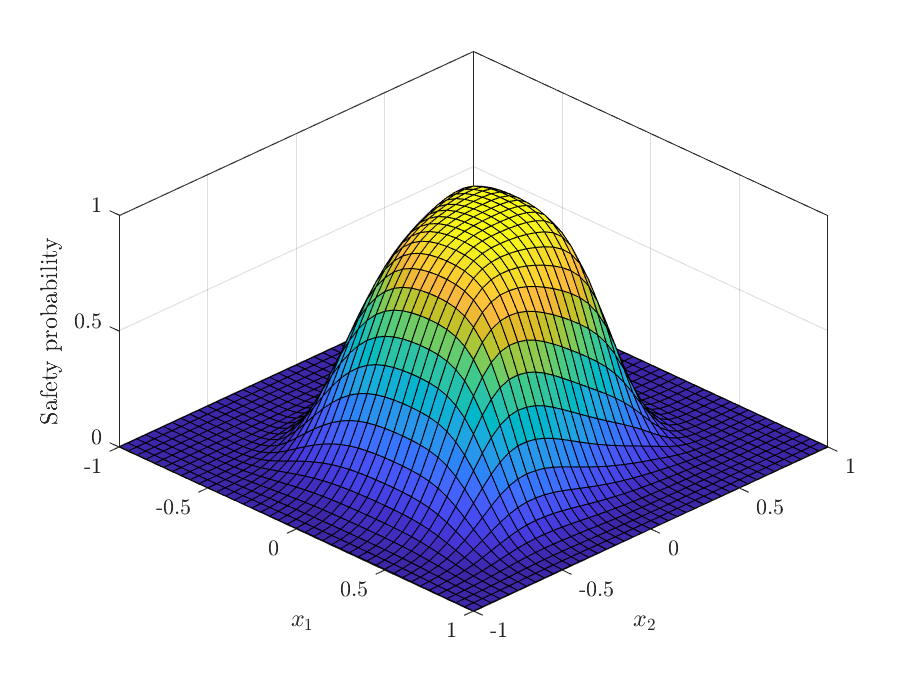

figure();
x1vec = cell_of_xvec_x3{1};
x2vec = cell_of_xvec_x3{2};
axis([axis_vec3 0 N]);
surf(x1vec,x2vec,reshape(prob_x3,length(x2vec),length(x1vec)));
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
zlabel('Safety probability')
box on
view(45, 45)

## Visualization of the safe initial sets --- Superlevel sets of safety probability

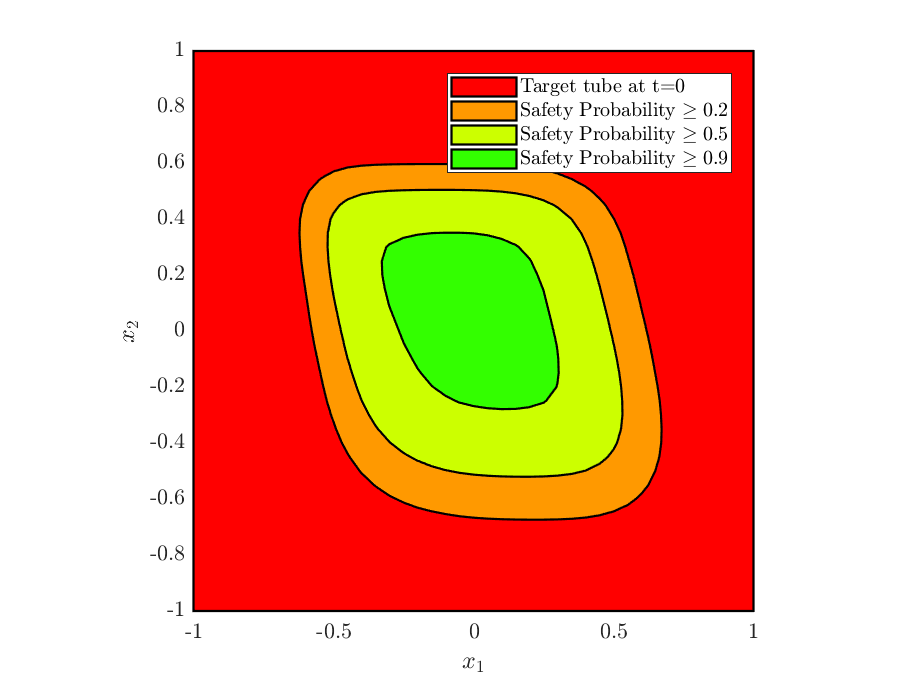

figure();
poly_array3 = getDynProgLevelSets2D(cell_of_xvec_x3, prob_x3, reach_set_thresholds, target_tube3);
hold on;
plot([target_tube3(1) poly_array3])
box on
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
axis(axis_vec3);
box on
axis equal
legend(legend_str)